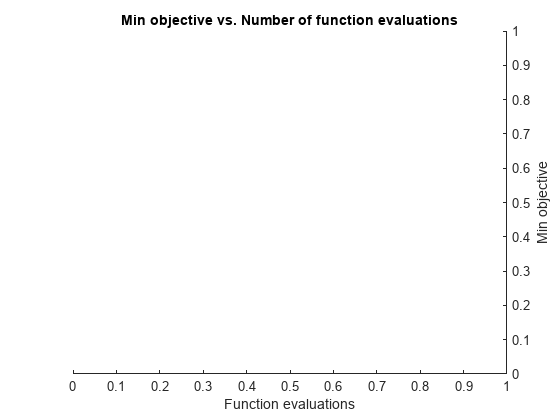

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       20.31% |       32.20% |       1.3910 |       1.3702 |          0.0688 |
|       1 |          50 |       00:00:10 |       56.25% |              |       1.0590 |              |          0.0688 |
|       1 |         100 |       00:00:14 |       50.00% |              |       0.9821 |              |          0.0688 |
|       1 |         150 |       00:00:16 |       48.44% |              |       0.9617 |              |          0.0688 |
|       1 |         200 |       

% balModes = ESPConst.BALANCE_MODES;
% for i=(1:length(balModes))
%     mode = balModes(i);
%     preprocessDatasets(true, mode);
% end
% 

datasets = dir(ESPConst.PATH_DATASET_PREPROCESSED + "*" + ESPConst.EXTENSION_DATA);
for i=1:length(datasets)
    path = ESPConst.PATH_DATASET_PREPROCESSED + datasets(i).name;
    [t, v] = prepareInput(path);
    bayesOptimizationLSTM(t, v, datasets(i).name);
end